close all
clear all

## Definition der Parameter

Definition der Lände $l$ des Fadens sowie der Anfangsauslenkung $\varphi_0$ (phi0) und der Beobachtungsdauer $beobd$.

g = 9.8; % Schwerbeschleunigung in m*s^(-2)
l = 3; % Länge des Fadens in m

phi0 = pi/4; % Anfangsauslenkung
beobd = 20; % Beobachtungsdauer
optionen = odeset('Events', @maximumsuche); % ode45-Option: Abbrechen nach 1 Periode

## Analytische Näherungslösung

Analytische Lösung der genäherten Differentialgleichung $\overset{..}{\varphi}+\frac{g}{l}*\varphi=0$.

**Definition der Differentialgleichung und den Anfangsbedingungen:**

syms phi(t)
ode = diff(phi, t, 2) + g/l * phi == 0

$$ode(t) = \frac{\partial^{2}}{\partial t^{2}}\varphi \left(t\right)+\frac{49\,\varphi \left(t\right)}{15}=0$$

phi_ = diff(phi,t);
bdg1 = phi(0) == phi0;
bdg2 = phi_(0) == 0;

**Analytisches Lösen der DGL, bestimmen der Kreisfrequenz **$\omega$** und der Periodendauer **$T$**:**

phi_analytisch = dsolve(ode, bdg1, bdg2)

$$phi\_analytisch = \frac{\pi \,\cos\left(\frac{7\,\sqrt{15}\,t}{15}\right)}{4}$$

w = sqrt(g/l);
T = 2*pi/w

T = 3.4764

**Grafische Darstellung der analytischen Lösung:**

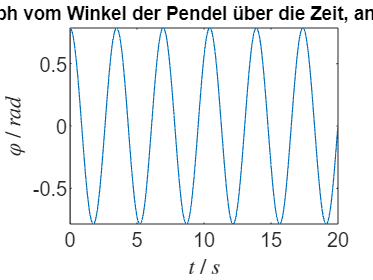

fplot(phi_analytisch, [0 beobd])
h=title('Graph vom Winkel der Pendel über die Zeit, analytisch');
h.FontSize=8;
xlabel('$t~/~s$', 'Interpreter','latex') 
ylabel('$\varphi~/~rad$', 'Interpreter','latex')

## Numerische Näherungs- und Exaktlösung

In diesem Abschnitt wird nicht nur die oben erwähnte Näherungslösung numerisch berechnet, sondern auch die exakte Lösung mit der Gleichung $\overset{..}{\varphi}+\frac{g}{l}*sin(\varphi)=0$ mithilfe von ode45(). Die Anfangsgeschwindigkeit wurde auf 0 gesetzt.

**Berechnung exakte Lösung:**

[t,u] = ode45(@(t,u) pendel(t,u,l), [0 beobd], [phi0 0]);

**Berechnung Näherungslösung:**

[t_n,u_n] = ode45(@(t,u) pendel_kleine_a(t,u,l), [0 beobd], [phi0 0]);

**Grafische Darstellung Winkel **$\varphi$** über Zeit **$t$** exakt vs. genähert:**

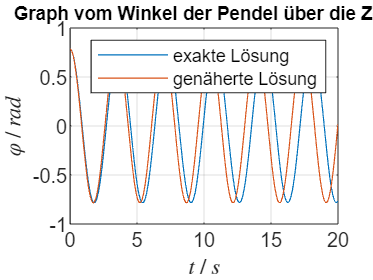

plot(t,u(:,1))
hold on
plot(t_n, u_n(:,1))
h=title('Graph vom Winkel der Pendel über die Zeit');
h.FontSize=8;
xlabel('$t~/~s$', 'Interpreter','latex') 
ylabel('$\varphi~/~rad$', 'Interpreter','latex')
legend('exakte Lösung', 'genäherte Lösung')
grid on
hold off

**Darstellung in kartesischen Koordinaten:**

In folgendem Plot wurde der Winkel $\varphi$ in kartesische Koordinaten umgerechnet und geplottet.

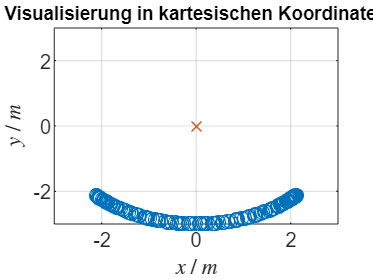

xkor = l * sin(u(:,1));
ykor = -l * cos(u(:,1));

plot(xkor, ykor, 'o')
hold on
plot(0,0,'x')
h=title('Visualisierung in kartesischen Koordinaten');
h.FontSize=8;
xlabel('$x~/~m$', 'Interpreter','latex') 
ylabel('$y~/~m$', 'Interpreter','latex') 
grid on
axis([-l l -l l])
hold off

## Bestimmen der Periodendauer der beiden Ansätze

Berechnet wird die Periodendauer der exakten Lösung $T_{exakt}$, der genäherten Lösung $T_{naeherung}$, der Differenz der beiden sowie die Änderungsrate. Umgesetzt durch eine Abbruchbedingung und erneutes Lösen der DGL.

[t_T, u_T] = ode45(@(t,u) pendel(t,u,l), [0 beobd], [phi0 0], optionen);
[t_n_T, u_n_T] = ode45(@(t,u) pendel_kleine_a(t,u,l), [0 beobd], [phi0 0], optionen);

T_exakt = t_T(end,1)

T_exakt = 3.6142

T_naeherung = t_n_T(end,1)

T_naeherung = 3.4760

T_diff = T_exakt - T_naeherung

T_diff = 0.1382

T_prozent = T_exakt/T_naeherung

T_prozent = 1.0398

## Periodendauer in Abhängigkeit der initialen Auslenkung

Analyse des nötigen $\varphi_0$ für bestimmte prozentuelle Abweichungen $(1~\%, 5~\%, 10~\%)$ zwischen $T_{exakt}$ und $T_{naeherung}$.

format short
target_percentages = [1, 5, 10]

target_percentages =      1     5    10


calculated_phi = zeros(1,length(target_percentages));

for i = 1:length(target_percentages)
    percent = target_percentages(i);
    calculated_phi(i) = fminsearch(@(phi) abweichung_periodendauer(phi, percent, l), pi/4);
end

calculated_phi

calculated_phi =     0.3991    0.8768    1.2130


Im folgenden Plot wird der allgemeine prozentuelle Unterschied zwischen den beiden Periodendauern in Abhängigkeit der initialen Auslenkung $\varphi_0$ ausgegeben. Bei den ebenfalls eingezeichneten Punkten handelt es sich um die im oberen Tiel berechneten Werte. 

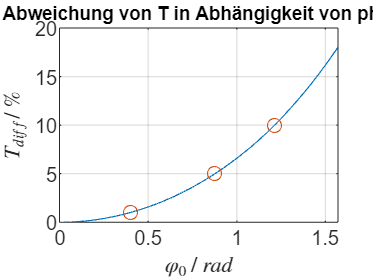

phi_abw = linspace(0,pi/2,100)';
abw_von_phi0 = zeros(1,length(phi_abw));

for i = 1:length(phi_abw)
abw_von_phi0(i) = abweichung_periodendauer_calc(phi_abw(i), l);
end
plot(phi_abw, abw_von_phi0)
hold on
grid on
plot(calculated_phi, target_percentages, 'o')
h=title('Abweichung von T in Abhängigkeit von phi0');
h.FontSize=8;
xlabel('$\varphi_0~/~rad$', 'Interpreter','latex') 
ylabel('$T_{diff}~/~\%$', 'Interpreter','latex') 
hold off

## Sekundenpendelbestimmung

In diesem Abschnitt wird bestimmt, wie die Länge $l$ des Fadenpendels bestimmt werden soll, um bei welcher initialen Auslenkung $\varphi_0$ den Zustand eines Sekundenpendels zu erreichen $(T=2~s)$ .

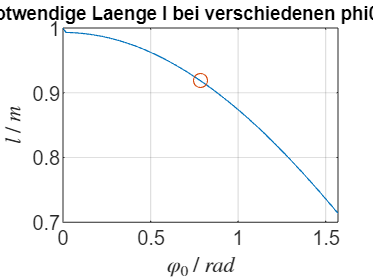

phi_abw = linspace(0,pi/2,100);
l_von_phi = zeros(1, length(phi_abw));
for i = 1:length(phi_abw)
    l_von_phi(i) = fminsearch(@(l) sekundenpendel_exakt(phi_abw(i), l), 1);
end
l_optimal = fminsearch(@(l) sekundenpendel_exakt(phi0, l), 1);
plot(phi_abw, l_von_phi)
hold on
plot(phi0, l_optimal, 'o')
h=title('Notwendige Laenge l bei verschiedenen phi0 (SP)');
h.FontSize=8;
xlabel('$\varphi_0~/~rad$', 'Interpreter','latex') 
ylabel('$l~/~m$', 'Interpreter','latex') 
grid on
hold off

## Bestimmung der Schwerbeschleunigung aus Messdaten

Aus einem gegebenen Datensatz aus Zeit, zugehörigem Winkel $\varphi$ sowie Winkelgeschwindigkeit $\overset{.}{\varphi}$ soll die Schwerbeschleunigung berechnet werden.

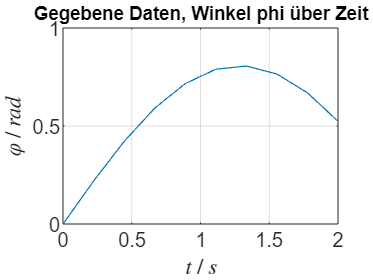

data = readmatrix('pendeldaten.csv');
plot(data(:,1), data(:,2))
xlabel('$t~/~s$', 'Interpreter','latex')
ylabel('$\varphi~/~rad$', 'Interpreter','latex')
h=title('Gegebene Daten, Winkel phi über Zeit');
h.FontSize=8;
grid on


laenge = 1

laenge = 1


params_opt = fminsearch(@(params) erdbeschl_min(params, laenge, data), [5, 1]);
gopt = params_opt(1)

gopt = 1.6200

phi0_punkt = params_opt(2)

phi0_punkt = 1.0000

## Koordinaten-Export

Erneutes Lösen der DGL im zu exportierenden Zeitintervall, umwandeln in Koordinaten und exportieren als .csv-Datei.

timespan = linspace(0, beobd, 250);
[t_export, u_export] = ode45(@(t,u) pendel(t,u,l), timespan, [phi0 0]);
phi_export = u_export(:,1)

phi_export =     0.7854
    0.7780
    0.7557
    0.7191
    0.6686
    0.6050
    0.5295
    0.4434
    0.3482
    0.2458



xkor_export = l * sin(phi_export);
ykor_export = -l * cos(phi_export);

Im letzten Abschnitt werden die Daten in eine CSV-Datei exportiert.

data = [l*ones(size(t_export)), xkor_export, ykor_export];
writematrix(data, 'coordinates.csv')